# Linearizing Nonlinear Aircraft Pitch Dynamics

**System Description (Nonlinear):**

We model simplified pitch dynamics using the following nonlinear equations:


$$
\dot{\theta} = q \\ 

\dot{q} = M_\alpha \alpha + M_q q + M_{\delta_e} \delta_e \\ 

\alpha = \theta - \gamma \approx \theta \quad\text{(angle of attack approx)} 

$$


�

Assumptions:

- Small-angle approximation: $\alpha \approx \theta$

- Inputs: elevator deflection $\delta_e$�

- States: $x = [\theta; q]$

Try to linearize the system model to a state-space representaion. 

## Method 1: Analynical solution

% Step 1: Define Symbolic Nonlinear Model
syms theta q delta_e real

% Parameters
M_alpha = -0.38;    % Pitch stiffness
M_q     = -1.2;     % Pitch damping
M_de    = -0.5;     % Elevator control effectiveness

% Define alpha (simplified)
alpha = theta; % assume gamma ≈ 0

% Nonlinear state equations
f1 = q;
f2 = M_alpha * alpha + M_q * q + M_de * delta_e;

f = [f1; f2];
x = [theta; q];
u = delta_e;

% Step 2: Compute Jacobians for Linearisation
% Linearisation: compute A and B matrices
A = jacobian(f, x);
B = jacobian(f, u);

% Evaluate at equilibrium: theta = 0, q = 0, delta_e = 0
A_lin = double(subs(A, {theta, q, delta_e}, {0, 0, 0}));
B_lin = double(subs(B, {theta, q, delta_e}, {0, 0, 0}));

% Step 3: Define Output Matrices and Construct State-Space
% Output: we measure both theta and q
C = eye(2);
D = zeros(2,1);

% State-space system
sys_pitch = ss(A_lin, B_lin, C, D);


With the parameters above:

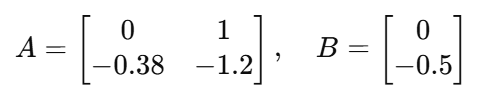

## Method 2: Numerical Linearisation from a Black-Box Model (similar to assignment 1 task)

Let’s assume the **nonlinear aircraft pitch model** is defined by a black-box function `pitch_dynamics(x, u)` that returns $\dot{x}$ given $x = [\theta; q]$and elevator input u.

% Step 1: Define the Function Handle
% shown at the end of this file

% Step 2: Linearise Numerically via Finite Differences
% Equilibrium point
x0 = [0; 0];      % [theta; q]
u0 = 0;
n = length(x0);
m = 1;            % scalar input
eps = 1e-6;       % small perturbation

% Evaluate nominal dx
f0 = pitch_dynamics(x0, u0);

% Estimate A matrix (df/dx)
A = zeros(n,n);
for i = 1:n
    dx = zeros(n,1);
    dx(i) = eps;
    f_perturb = pitch_dynamics(x0 + dx, u0);
    A(:,i) = (f_perturb - f0) / eps;
end

% Estimate B matrix (df/du)
du = eps;
f_perturb_u = pitch_dynamics(x0, u0 + du);
B = (f_perturb_u - f0) / du;

% Step 3: Construct the Linear System
C = eye(2);
D = zeros(2,1);
sys_pitch = ss(A, B, C, D)

sys_lin =
 
  A = 
          x1     x2
   x1      0      1
   x2  -0.38   -1.2
 
  B = 
         u1
   x1     0
   x2  -0.5
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



function dx = pitch_dynamics(x, u)
    % Parameters (hidden inside black box)
    M_alpha = -0.38;
    M_q     = -1.2;
    M_de    = -0.5;

    theta = x(1);
    q     = x(2);
    alpha = theta;

    dx = zeros(2,1);
    dx(1) = q;
    dx(2) = M_alpha * alpha + M_q * q + M_de * u;
end